clear; clc; close all;
syms x(t) zeta omega_n omega F_0 x_0 x_dot_0

v = diff(x, t);
a = diff(x, t, 2);
eq = a + 2*zeta*omega_n*v + omega_n^2*x == F_0*cos(omega*t)

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\zeta \,\omega_{n}\,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)\,{\omega_{n}}^{2}=F_{0}\,\cos\left(\omega \,t\right)$$

#### Variation with $\zeta$

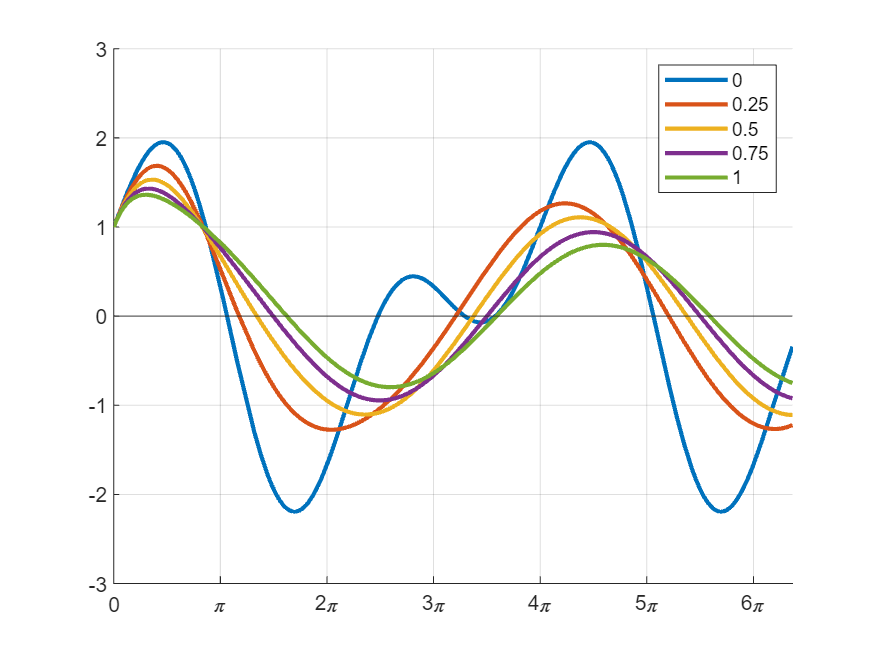

zeta_array = [0, 0.25, 0.5, 0.75, 1];

figure; hold on;
for i=1:length(zeta_array)
    x_sol = dsolve(subs(eq, zeta, zeta_array(i)), x(0)==x_0, v(0)==x_dot_0);
    x_sol = simplify(expand(rewrite(x_sol, "sincos")));

    if(zeta_array(i) == 0)
        x_sol_undamped = x_sol;
    end

    x_sol = subs(x_sol, [x_0, x_dot_0, omega_n, F_0, omega], [1, 1, 1, 1, 0.5]);
    

    fplot(x_sol, [0, 20], LineWidth=2); hold on;
    ylim([-3 3])
    
    
end
grid on;
xticks([0, pi, 2*pi, 3*pi, 4*pi, 5*pi, 6*pi]);
xticklabels({'0', '\pi','2\pi','3\pi','4\pi','5\pi','6\pi'})
yline(0);
legend("0", "0.25", "0.5", "0.75", "1");

#### Resonance (happens when $\omega$ = $\omega_n$)

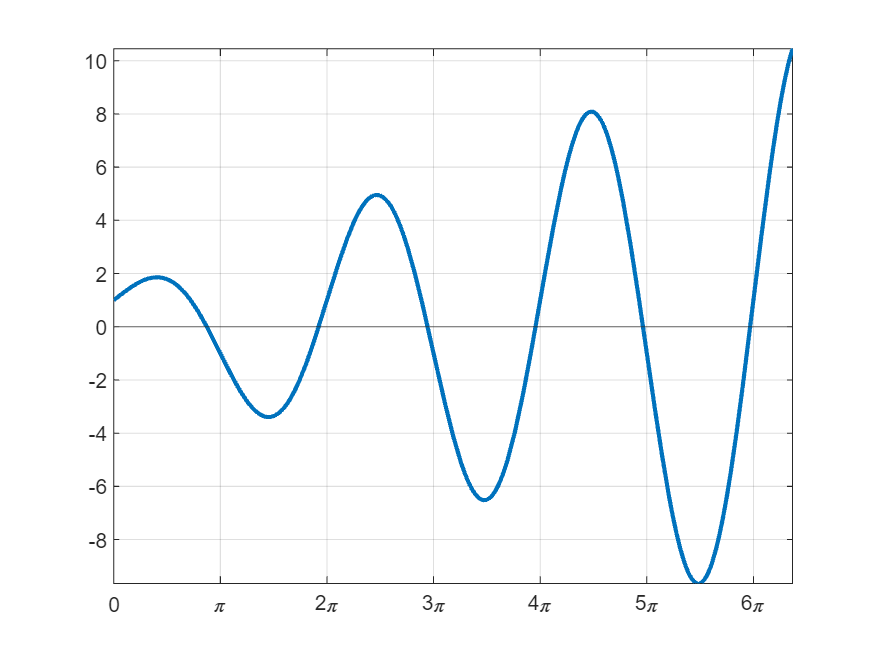

x_sol_undamped = subs(x_sol_undamped, [x_0, x_dot_0, omega_n, F_0], [1, 1, 1, 1]);

x_sol_resonance = limit(x_sol_undamped, omega, 1);
figure; 
fplot(x_sol_resonance, [0, 20], LineWidth=2); hold on; 
grid on;
xticks([0, pi, 2*pi, 3*pi, 4*pi, 5*pi, 6*pi]);
xticklabels({'0', '\pi','2\pi','3\pi','4\pi','5\pi','6\pi'})
yline(0);

#### Beats (happens when $\omega$ becomes close to $\omega_n$)

figure; hold on;

x_sol = dsolve(subs(eq, zeta, 0), x(0)==x_0, v(0)==x_dot_0);
x_sol = simplify(expand(rewrite(x_sol, "sincos")));


omega_n_val = 1;
omega_val = 0.9;
omega_avg = (omega_val + omega_n_val)/2;
omega_delta = omega_n_val - omega_val;

x_sol = subs(x_sol, [x_0, x_dot_0, omega_n, F_0, omega], [1, 1, omega_n_val, 1, omega_val])

$$x\_sol = \frac{100\,\cos\left(\frac{9\,t}{10}\right)}{19}-\frac{81\,\cos\left(t\right)}{19}+\sin\left(t\right)$$

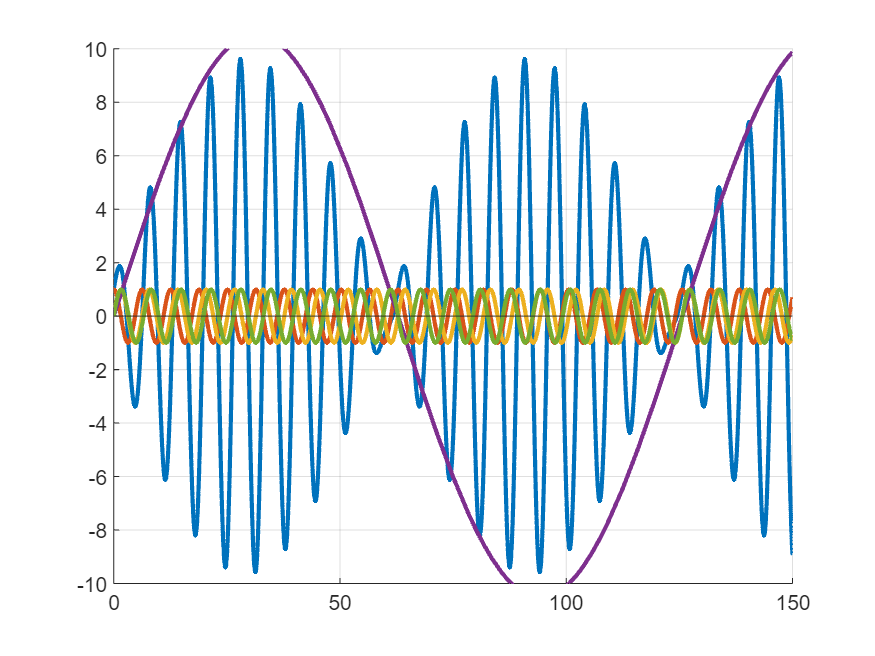



fplot(x_sol, [0, 150], LineWidth=2); hold on; 
fplot(cos(t), [0, 150], LineWidth=2);
fplot(sin(t), [0, 150], LineWidth=2);
exp1 = (sin(omega_delta*t/2)/(omega_avg*omega_delta));
exp2 = sin(omega_avg*t);
fplot(exp1, [0, 150], LineWidth=2);
fplot(exp2, [0, 150], LineWidth=2);
ylim([-10 10])
    
grid on;

yline(0);